# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 김나현**

**학번**** : 201917549**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :  https://github.com/knahyun/dsp_hw2.git**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x = [1,2,2,1]; N = 4;
Xk = dft(x,N);
magX = abs(Xk), phaX = angle(Xk)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


Xk = [6,-1-j,0,-1+j]; N = 4;
x = idft(Xk,N);
magX = abs(x), phaX = angle(x)*180/pi

magX =      1     2     2     1


phaX = 	1.0e+-13 *

         0   -0.0159   -0.0398    0.1113


n = 0:3; x = [1,2,2,1];
k = 0:3; w = (pi/4)*k;
X = x * (exp(-j*n'*w))

X =    6.0000 + 0.0000i   1.7071 - 4.1213i  -1.0000 - 1.0000i   0.2929 - 0.1213i


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x = [1,2,2,1, zeros(1,12)]; N = 16;
Xk_2 = dft(x,N);
magX = abs(Xk_2), phaX = angle(Xk_2)*180/pi

magX =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


Xk = Xk_2; N = 16;
x = idft(Xk,N);
magX = abs(x), phaX = angle(x)*180/pi

magX =     1.0000    2.0000    2.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


phaX =     0.0000    0.0000   -0.0000   -0.0000  -31.1225  -51.0959  -48.8879  -69.7751  -74.8760  -90.0000  -90.0000 -111.1613 -120.0333 -131.8452 -145.6388 -157.6938


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

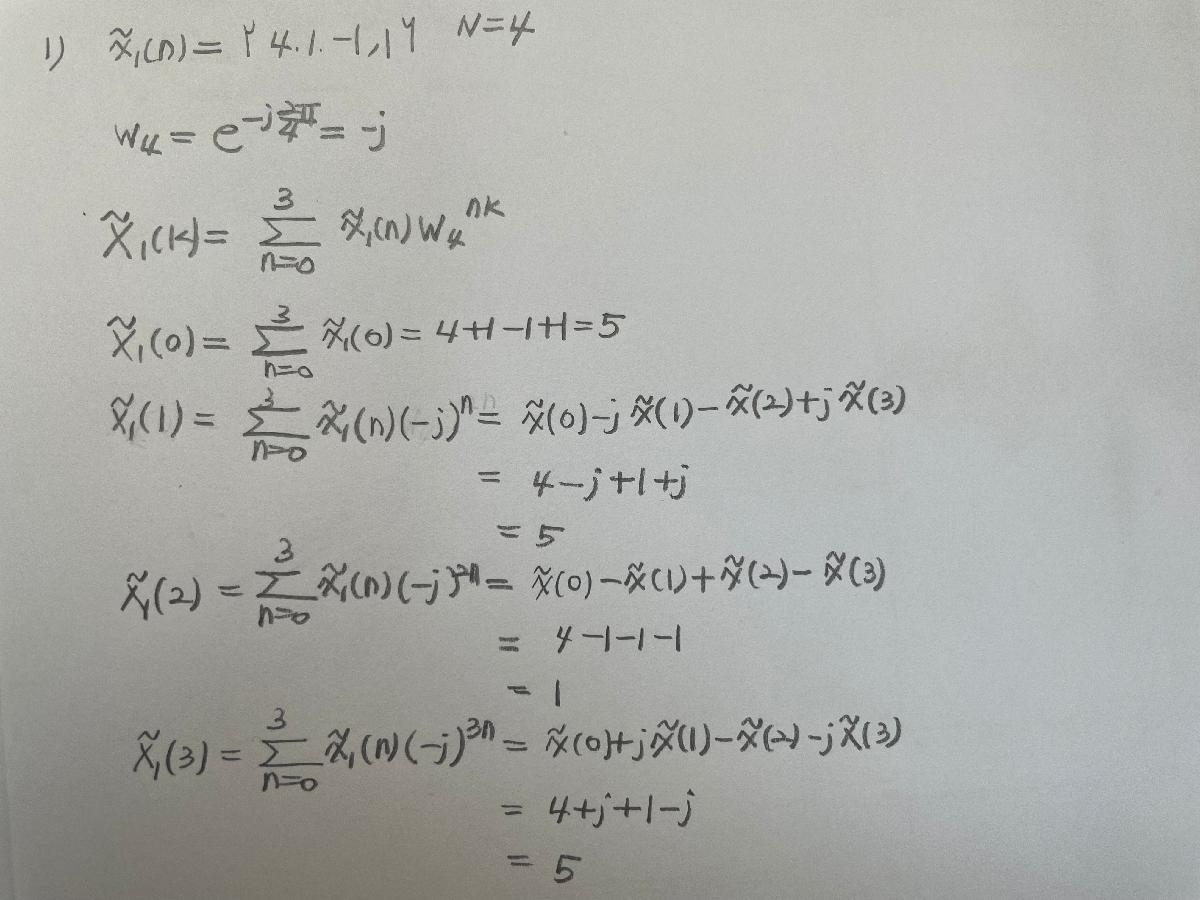

xn1 = [4,1,-1,1]; N = 4;
Xk1 = dfs(xn1,N)

Xk1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

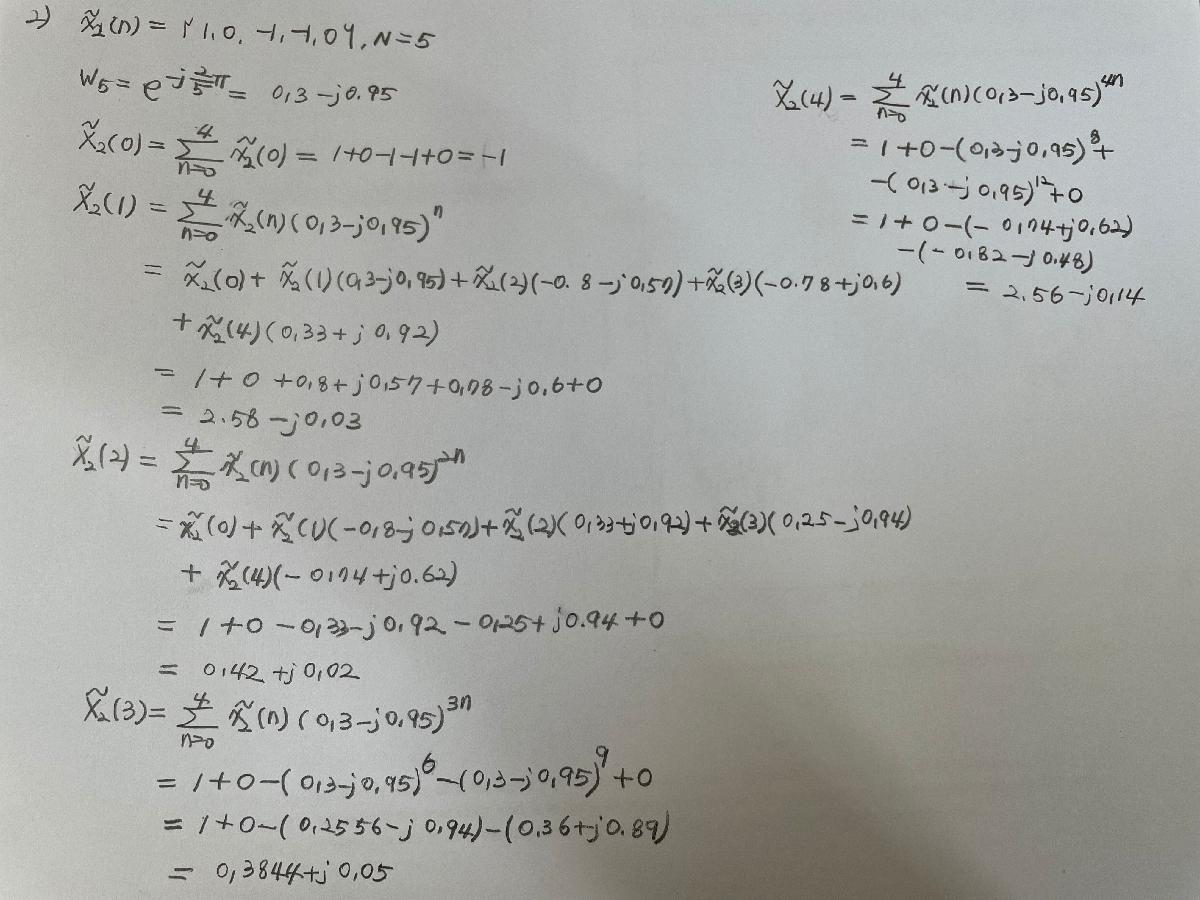

xn2 = [1,0,-1,-1,0]; N = 5;
Xk2 = dfs(xn2,N)

Xk2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

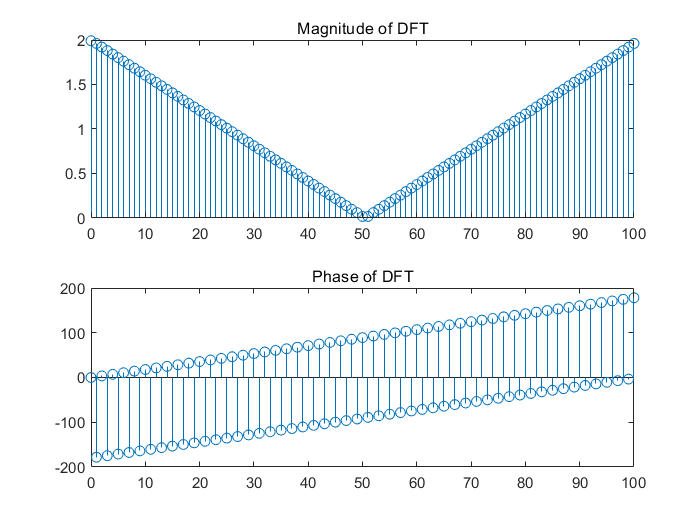

n = [0:100]; xn = sinc((n-50)/2).^2; 
N = length(xn); k = 0:N-1;
Xk = dft(xn,N);
mag_Xk = abs(Xk); pha_Xk = angle(Xk)*180/pi;
figure(1);
subplot(2,1,1); stem(k,mag_Xk);
title('Magnitude of DFT');
subplot(2,1,2); stem(k,pha_Xk);
title('Phase of DFT');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

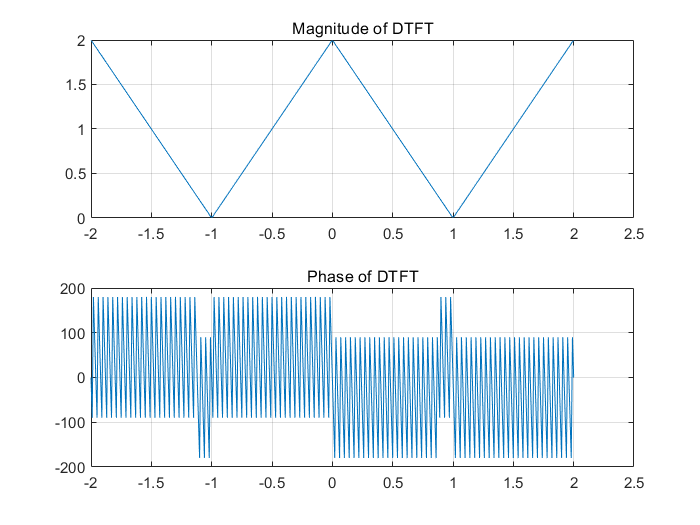

n1 = 0:100; x1 = sinc((n1-50)/2).^2; 
k = -200:200; w = (pi/100)*k;
X1 = x1 * (exp(-j*pi/100)) .^ (n1'*k);
mag_X1 = abs(X1); pha_X1 = angle(X1)*180/pi;
figure(2);
subplot(2,1,1); plot(w/pi,mag_X1); 
title('Magnitude of DTFT'); grid; 
subplot(2,1,2); plot(w/pi,pha_X1); 
title('Phase of DTFT'); grid; 

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

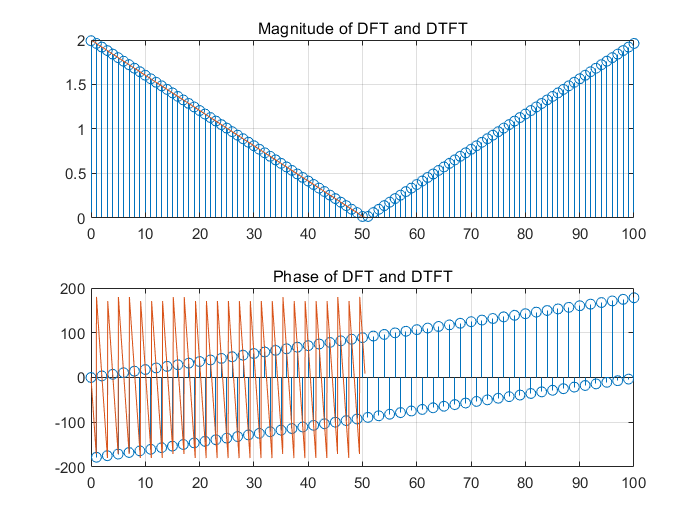

n = 0:100; xn = sinc((n-50)/2).^2; N = length(xn);
Xk = dft(xn,N); k = 0:N-1;
mag_Xk = abs(Xk); pha_Xk = angle(Xk)*180/pi;
subplot(2,1,1); stem(k,mag_Xk); 
title('Magnitude of DFT and DTFT'); hold on
subplot(2,1,2); stem(k,pha_Xk); 
title('Phase of DFT and DTFT'); hold on

[X,w] = freqz(xn,1,1000);
mag_X = abs(X); pha_X = angle(X)*180/pi;
Dw = (2*pi)/N;
subplot(2,1,1); plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

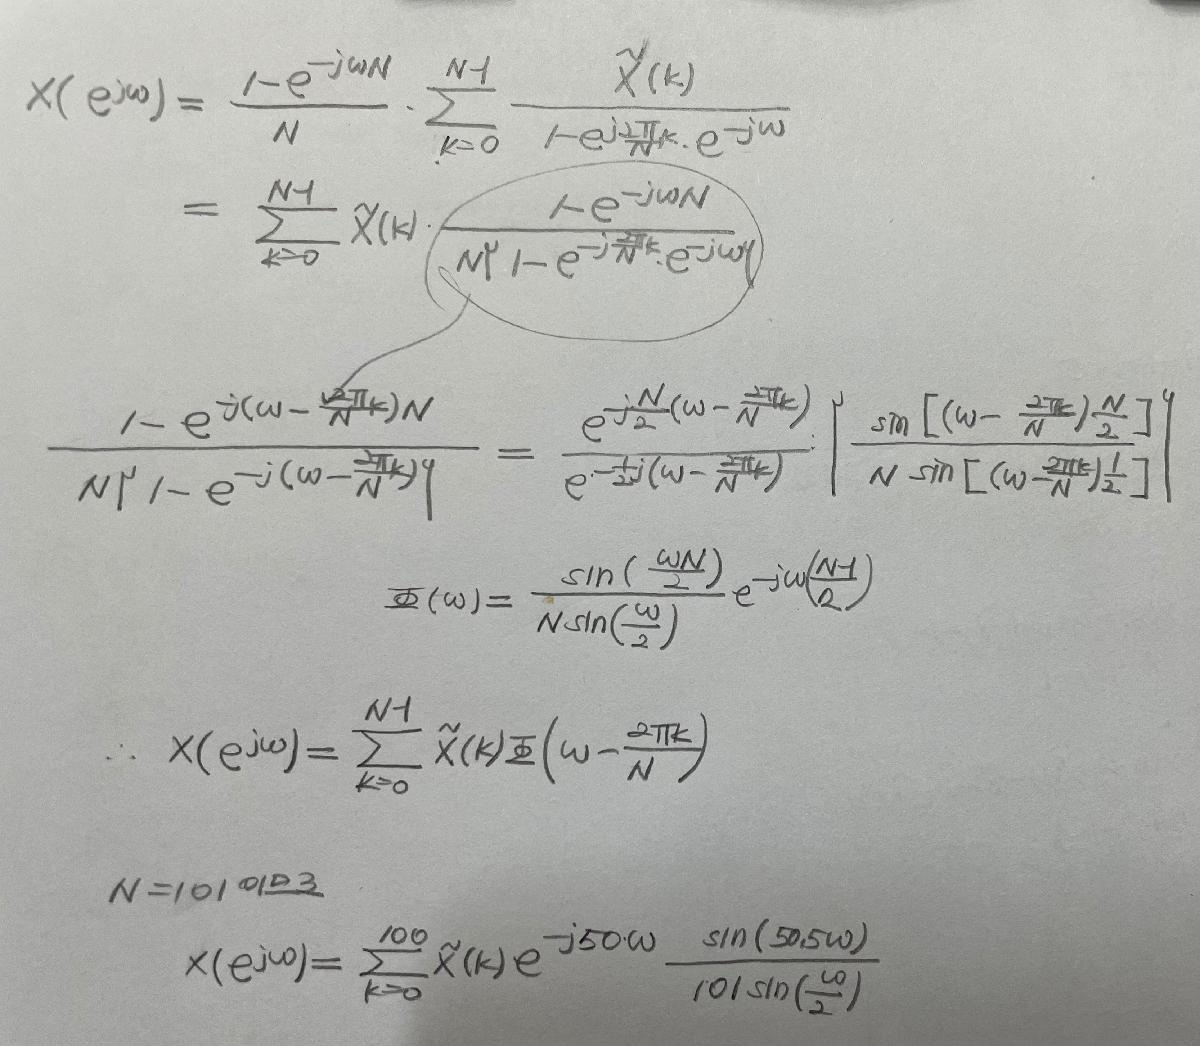

function [Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [Xk] = dft(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [xn] = idft(Xk,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end
